clear;clc;

%Parámetros motor
Ra = 0.635;
La = 0.0883;
Ki = 0.00943;
Kb = 1010;
Jm = 330;
Bm = 0.001;

%Función de transferencia

G = tf(Ki/(La*Jm),[1 (Bm/Jm + Ra/La) (Ra*Bm+Ki*Kb)/(La*Jm)])


G =
 
        0.0003236
  ----------------------
  s^2 + 7.191 s + 0.3269
 
Continuous-time transfer function.


p = pole(G)

p =    -7.1457
   -0.0457


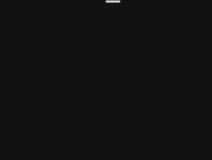


figure; grid on;
subplot(2,1,1); grid on;
step(G) %respuesta al escalón
subplot(2,1,2); grid on;
rlocus(G) %LGR

%Parámetros de diseño
Mp = 0.1;
tss = 1;

damp = log(1/Mp)/(sqrt(pi^2+log(1/Mp)^2)) %Amortiguamiento

damp = 0.5912

frec_n = 4/(damp*tss) %Frecuencia natural no amortiguada

frec_n = 6.7664


%Función de transferencia ideal
Gideal = tf(frec_n^2,[1 2*damp*frec_n frec_n^2])


Gideal =
 
        45.78
  -----------------
  s^2 + 8 s + 45.78
 
Continuous-time transfer function.


pole(Gideal)

ans =   -4.0000 + 5.4575i
  -4.0000 - 5.4575i



figure;hold on;

p_ideal = pole(Gideal)

p_ideal =   -4.0000 + 5.4575i
  -4.0000 - 5.4575i


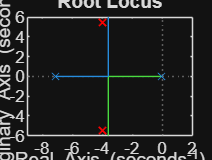


plot(real(p_ideal(1)),imag(p_ideal(1)),'x','Color',"r",'LineWidth',1)
plot(real(p_ideal(2)),imag(p_ideal(2)),'x','Color',"r",'LineWidth',1)
rlocus(G)

xlim([-9 2])
ylim([-6 6])

%Ángulo de compensación
phi = 180 - 180/pi*(angle(p_ideal(1)-p(2))) - 180/pi*(angle(p_ideal(1) - p(1)))

phi = -5.9666


%Cero del compensador
zc = p(1)

zc = -7.1457

T = -1/zc

T = 0.1399


%Polo del compensador
pc = real(p_ideal(1)) - imag(p_ideal(1))/tan(angle(p_ideal(1) - p(1)) + phi*pi/180)

pc = -7.9543

ac = -1/(pc*T)

ac = 0.8983


Gcomp = tf([1 -zc],[1 -pc])


Gcomp =
 
  s + 7.146
  ---------
  s + 7.954
 
Continuous-time transfer function.



%Función de transferencia compensada K=1

Gx = series(Gcomp,G)


Gx =
 
      0.0003236 s + 0.002312
  -------------------------------
  s^3 + 15.15 s^2 + 57.53 s + 2.6
 
Continuous-time transfer function.


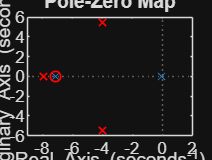


figure;hold on;

plot(real(p_ideal(1)),imag(p_ideal(1)),'x','Color',"r",'LineWidth',1)
plot(real(p_ideal(2)),imag(p_ideal(2)),'x','Color',"r",'LineWidth',1)
plot(pc,0,'x','Color',"r",'LineWidth',1)
plot(zc,0,'o','Color',"r",'LineWidth',1)
pzmap(G)

xlim([-9 2])
ylim([-6 6])
xlim([-9 2])
ylim([-6 6])

hold off;

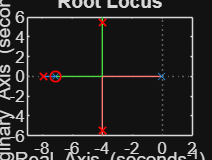


figure;hold on;

plot(real(p_ideal(1)),imag(p_ideal(1)),'x','Color',"r",'LineWidth',1)
plot(real(p_ideal(2)),imag(p_ideal(2)),'x','Color',"r",'LineWidth',1)
plot(pc,0,'x','Color',"r",'LineWidth',1)
plot(zc,0,'o','Color',"r",'LineWidth',1)
rlocus(Gx)

xlim([-9 2])
ylim([-6 6])
xlim([-9 2])
ylim([-6 6])

%Ganancia del compensador

Kc = 1/(Kb*abs(evalfr(G,p_ideal(1)))*abs(evalfr(Gcomp,p_ideal(1))))

Kc = 138.9612


Gcomp = tf([Kc -Kc*zc],[1 -pc])


Gcomp =
 
  139 s + 993
  -----------
   s + 7.954
 
Continuous-time transfer function.



%Función de transferencia compensada

Gx = series(Gcomp,G)


Gx =
 
        0.04497 s + 0.3213
  -------------------------------
  s^3 + 15.15 s^2 + 57.53 s + 2.6
 
Continuous-time transfer function.


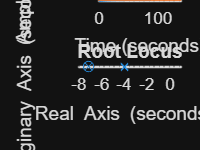


M = feedback(Gx,Kb); %Lazo completo

figure;
subplot(2,1,1);hold on;
step(G) %Sin compensar
step(M) %Compensado
subplot(2,1,2);
rlocus(M)

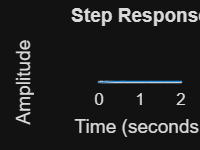

figure;
step(M,2) %Compensado

%Circuito RLC

R=22

R = 22

L=500e-6

L = 5.0000e-04

C=220e-6

C = 2.2000e-04


GRLC = tf(1/(L*C),[1 R/L 1/(L*C)])


GRLC =
 
          9.091e06
  ------------------------
  s^2 + 44000 s + 9.091e06
 
Continuous-time transfer function.


p_rlc = pole(GRLC) %primer orden

p_rlc = 1.0e+04 *

   -4.3792
   -0.0208


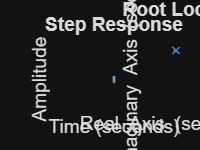

d_rlc = 0.4037

fn_rlc = 198.1607


GRLCi =
 
         3.927e04
  ----------------------
  s^2 + 160 s + 3.927e04
 
Continuous-time transfer function.


p_rlci = 1.0e+02 *

  -0.8000 + 1.8129i
  -0.8000 - 1.8129i



figure;
subplot(1,2,1);step(GRLC);
subplot(1,2,2);rlocus(GRLC)